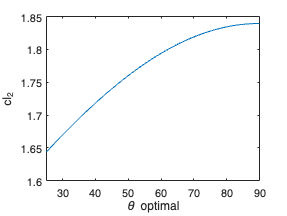

start_angle = 25;
theta_max = [linspace(start_angle,90,1000)]*pi/180;
theta_opt = theta_max;
syms x_m y_g
cl_1 = 1.5;
h_bak = 0.24;
theta_platform = asin((sin(theta_max)*(cl_1-h_bak))/cl_1);
cl_2 = cl_1 + sqrt(2)*h_bak*sin(theta_opt);

%plot van cl_2
plot(theta_max*180/pi,cl_2)
xlim([start_angle,90]);
xlabel('\theta optimal')
ylabel('cl_2')

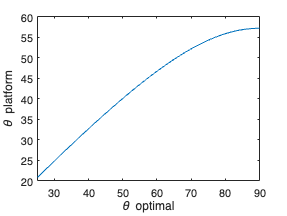



%cl_2 = cl_1.*(sin(theta_opt)./sin(theta_platform));  % dit geeft een constante waarde.
plot(theta_max*180/pi,theta_platform*180/pi)
xlim([start_angle,90]);
xlabel('\theta optimal')
ylabel('\theta platform')

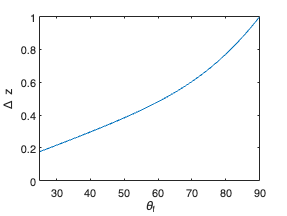


dy = cl_2.*cos(theta_platform) - cl_1*cos(theta_opt);
plot(theta_max*180/pi,dy)
xlim([start_angle,90]);
xlabel('\theta_f')
ylabel('\Delta z')

y_eind = cl_1 - cl_2.*cos(theta_platform);


## we hebben enkele benaderingen gemaakt die enkel werken voor grote hoeken. Aangezien dit ons doel is zullen we de kleinere hoeken verwaarlozen in de trade-off en zoeken naar een tweede minimale.

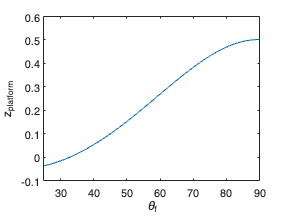



[M,I]= max(y_eind);
plot(theta_max*180/pi,y_eind)
xlim([start_angle,90]);
hold on

hold off
xlabel('\theta_f')
ylabel('z_{platform}')

theta_max(I)*180/pi

ans = 90

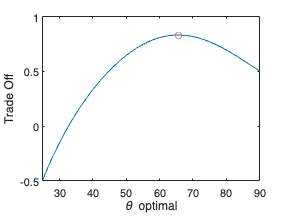

exponent = 1.5;
trade_off = y_eind./dy.^(exponent);
[M,I]= max(trade_off);
plot(theta_max*180/pi,trade_off)
hold on
scatter(theta_max(I)*180/pi , trade_off(I))
xlim([start_angle,90]);
hold off
xlabel('\theta optimal')
ylabel('Trade Off')




optimal_angle = theta_max(I)*180/pi

optimal_angle = 65.6006

platform_angle = theta_platform(I)*180/pi

platform_angle = 49.9050

end_position_platform = [x_m + round(cl_1*sin(theta_platform(I)),2);y_g + round(cl_1-cl_1*cos(theta_platform(I)),2)]

$$end\_position\_platform = \left(\begin{array}{c} x_{m}+\frac{23}{20}\\ y_{g}+\frac{53}{100} \end{array}\right)$$

height_drop = dy(I)

height_drop = 0.5455

final_height = y_eind(I)

final_height = 0.3348